# Sandbox

UWCC Structural Analysis: Heerod Sahraei

Run test scripts in here after running Main.mlx

### Cross Section Visualizer

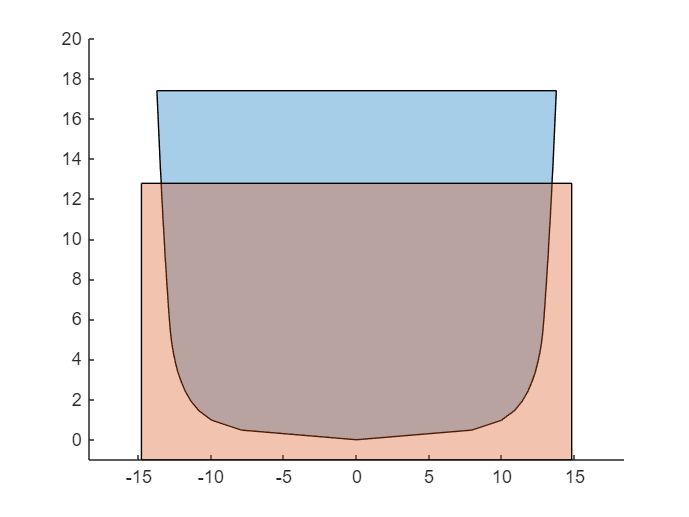

index = 17; % station (between 1 and # crosssections)
xPos = xUnique(index);
waterline_guess = 12.6+ zmin_all;
trim_guess = -0.01;
warning('off', 'all');
shape = internalShapes(index);
box = waterbox(waterline_guess + tan(trim_guess) * xPos, 1);
clf;
hold on;
ylim([-1 20]);
xlim([-zmax_all - 1 zmax_all + 1]);
plot(shape);
plot(box);
hold off;

% polyshape is weird asf and doesnt like when you try to transform it 3d.
% have to use patch and some weird Vertices bs
% hold on;
% view(3);
% for i = 1:numel(xUnique)
%     shape = internalShapes(i);
%     positions = shape.Vertices;
%     positions(:,3) = xUnique(i);
%     patch(positions(:,1),positions(:,2),positions(:,3));
%     axis vis3d
% end
% hold off;

### Finding the necessary load for a desired Freeboard

freeboard = 10.7; % (in)
draft_ideal = zmax_all - freeboard;
weightInitial = 400;
netforcefromweight = @(weight) trapz(xInterp,selfWeightInterp) ...
    + trapz(xUnique,buoyantdist([draft_ideal,0])) - weight;
objective = @(weight) (netforcefromweight(weight))^2 ; % squaring turns 0 into a local min
[weightIdeal, resultant] = fminsearch(objective,weightInitial,optimset('Display', 'off'));
disp("weight necessary for desired freeboard (lbf):  " + weightIdeal/LIVE_FACTOR);

weight necessary for desired freeboard (lbf):  174.97


### Lol what if the whole canoe was filled with water and we had to put it on stands?

- Question from Paddling Team

standSeperation = 0;

standSeperation = 0